# Modelo 7

Es un modelo logístico, más realista que los anteriores, ya que consideramos $f\left(P\left(t\right)\right)\;$**no lineal**.


$$\frac{\textrm{dP}}{\textrm{dt}}=f\left(P\left(t\right)\right)$$



$$\textrm{con}\;f\left(P\left(t\right)\right)=k_o +k_1 P\left(t\right)+k_2 P^2 \left(t\right)+\ldotp \ldotp \ldotp$$


Solo nos quedamos hasta orden 2.


$$\frac{\textrm{dP}}{\textrm{dt}}=k_o +k_1 P\left(t\right)+k_2 P^2 \left(t\right)$$


- **Condición 1**: sin población no hay crecimiento. $\frac{\textrm{dP}}{\textrm{dt}}=$0 cuando $\mathrm{P}=0$ 

            
$$0=k_o +k_1 \cdot 0+k_2 \cdot 0\;\to k_o =0$$


- Condición 2: la población tiene un máximo. $\frac{\textrm{dP}}{\textrm{dt}}=0$ cuando $P\;=P_{\max } \not= 0$

            
$$0=k_1 \cdot P_{\max } +k_2 \cdot {P^2 }_{\max } \to k_2 =-\frac{k_1 }{P_{\max } }$$


clc, clear
syms P Pmax k0 k1 k2 
f(P) = k0 + k1*P + k2*P^2

$$f(P) = k_{2}\,P^{2}+k_{1}\,P+k_{0}$$

% condición 1
k0_subs = solve(f(0) == 0,k0)

$$k0\_subs = 0$$

% sustituyo
f(P) = subs(f,k0, k0_subs)

$$f(P) = k_{2}\,P^{2}+k_{1}\,P$$

% condición 2
k2_subs = solve(f(Pmax) == 0, k2)

$$k2\_subs = -\frac{k_{1}}{\mathrm{Pmax}}$$

% sustituyo
f(P) = subs(f,k2, k2_subs)

$$f(P) = P\,k_{1}-\frac{P^{2}\,k_{1}}{\mathrm{Pmax}}$$


$$\frac{\mathrm{dP}}{\mathrm{dt}}=k\cdot P\cdot \left(1-\frac{P}{P_{\max } }\right)$$


### 1. Resolución de la EDO

clc, clear
syms P(t) P0 t0 k Pmax

edo = diff(P, t, 1) == P*k*(1-P/Pmax);
cond = [P(t0)==P0];
P(t) = dsolve(edo, cond)

$$P(t) = P_{0}\,{\mathrm{e}}^{\frac{k\,t\,\left(\mathrm{Pmax}-1\right)}{\mathrm{Pmax}}}\,{\mathrm{e}}^{-\frac{k\,t_{0}\,\left(\mathrm{Pmax}-1\right)}{\mathrm{Pmax}}}$$

#### 2. Sustitución de valores iniciales y constante r

k_values = [0.08, 0.05, 0.06];
P_max = [200 300 100]

P_max =    200   300   100


ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

#### 3. Gráfica para cada caso

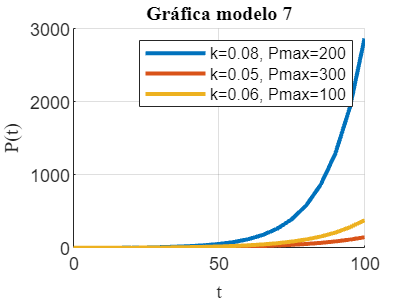

figure;
hold on;
for i = 1:n
    P_subs = subs(P, [k Pmax t0, P0], [k_values(i), P_max(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    P_values = subs(P_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, P_values, 'LineWidth', 2, 'DisplayName', ['k=' num2str(k_values(i)) ', Pmax=' num2str(P_max(i))]);
end

xlabel('t','FontName','latex');
ylabel('P(t)','FontName','latex');
title('Gráfica modelo 7','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad


$$\frac{\mathrm{dP}}{\mathrm{dt}}=k\cdot P\cdot \left(1-\frac{1}{P_{\max } }\right)$$


Para $k>0;P>0;P<P_{\max } \;\to \frac{\textrm{dP}}{\textrm{dt}}=0$

En estacionario $\frac{\textrm{dP}}{\textrm{dt}}=0\;\textrm{si}\;\;P=0\;\;o\;P=P_{\max }$

Si diferenciamos la ecuación con respecto al tiempo:


$$\frac{d^2 P}{{\textrm{dt}}^2 }=k\cdot \frac{\textrm{dP}}{\textrm{dt}}\cdot \left(1-\frac{2P}{P_{\max } }\right)$$


edo2 = diff(edo,t,1)

$$edo2(t) = \frac{\partial^{2}}{\partial t^{2}}P\left(t\right)=-k\,\left(\frac{1}{\mathrm{Pmax}}-1\right)\,\frac{\partial }{\partial t}P\left(t\right)$$

Con condiciones:

 $\frac{d^2 P}{\textrm{dt}}=0$ (punto de inflexión)

Entonces o$\lbrace$ $\begin{array}{l}
\to \frac{\textrm{dP}}{\textrm{dt}}=0\;\left(\textrm{trivial}\right)\\
\to P=\frac{P_{\max } }{2}
\end{array}$

Cuando $\begin{array}{l}
P<\frac{P_{\max } }{2}\to \textrm{crecimiento}\\
P>\frac{P_{\max } }{2}\to \textrm{decrecimiento}
\end{array}$

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo7_circuit";

Condiciones iniciales y constantes del modelo:

k_values = [-1 2 3];
P_max = [100, 101, 150]

P_max =    100   101   150


ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
P1 = signals{1}.Values.Data

P1 = 1.0e+19 *

   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000


P = signals{2}.Values.Data

P = 1.0e+19 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


signal_time = signals{1}.Values.Time;
P1(1,1) -2 % no están vacíos

ans = -2.9900

#### Gráfica 1

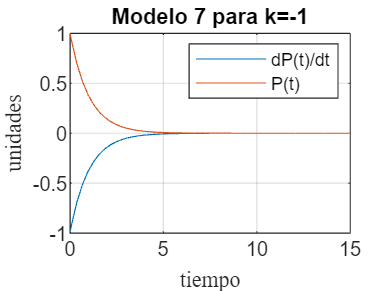

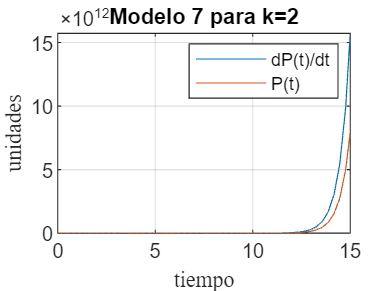

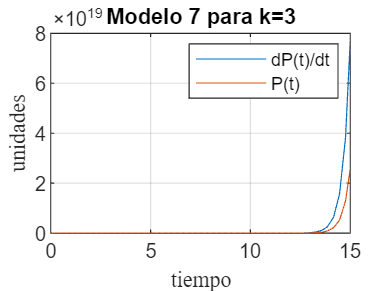

[m, n] = size(P1);
for i =1:n
    figure
    plot(signal_time, P1(:,i))
    hold on
    plot(signal_time, P(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 7 para k=' num2str(k_values(i))]);
    legend('dP(t)/dt','P(t)');
    hold off
end 

#### Gráfica 2

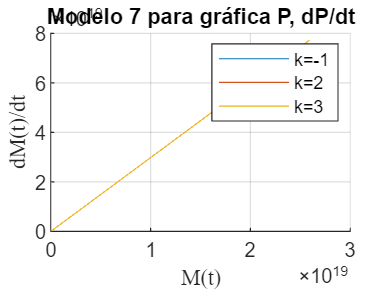

[m, n] = size(P1);
figure;
hold on;
for i =1:n
    plot(P(:,i), P1(:,i), 'DisplayName', ['k=' num2str(k_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 7 para gráfica P, dP/dt');
    hold on
end 
legend('show')

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.